Settings for script

warning off
fontSize = 25;

Load and visualise STL files

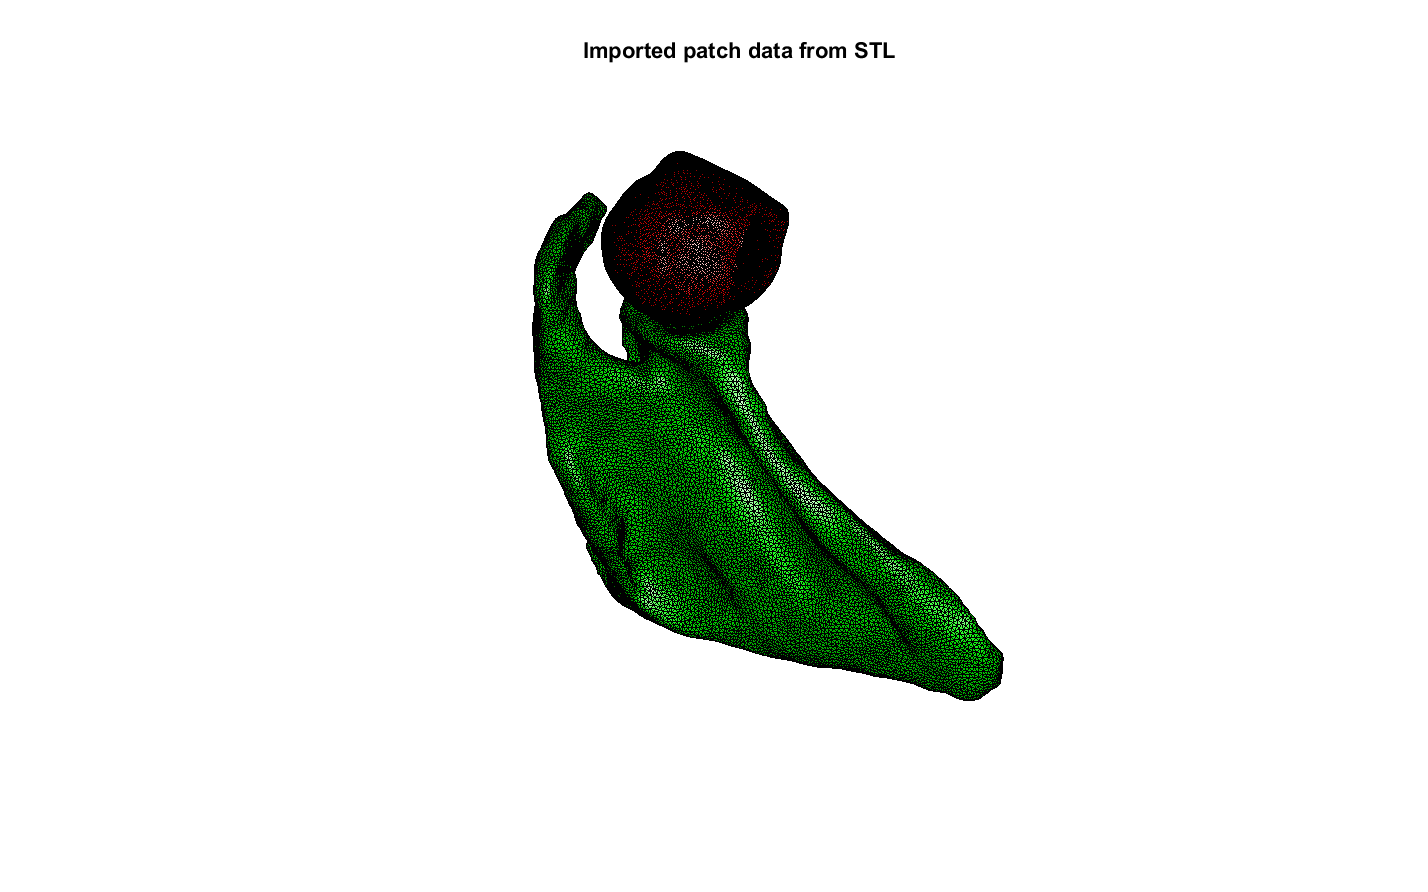

% % % %Load STLs
% % % scapulaSTL = import_STL('Scapula_r_GlenoidCS.stl');
% % % humerusSTL = import_STL('HumeralHeadCut_r_GlenoidCS.stl');
% % % 
% % % %Extract the faces and vertices
% % % scapulaF = scapulaSTL.solidFaces{1};
% % % scapulaV = scapulaSTL.solidVertices{1};
% % % humerusF = humerusSTL.solidFaces{1};
% % % humerusV = humerusSTL.solidVertices{1};
% % % 
% % % %Merge vertices
% % % [scapulaF,scapulaV] = mergeVertices(scapulaF,scapulaV);
% % % [humerusF,humerusV] = mergeVertices(humerusF,humerusV);
% % % 
% % % %Plot the models
% % % cFigure;
% % % title('Imported patch data from STL','fontSize',25);
% % % gpatch(scapulaF,scapulaV,'g');
% % % hold on
% % % gpatch(humerusF,humerusV,'r');
% % % axisGeom;
% % % camlight('headlight');
% % % lighting phong; axis off;

% % % drawnow;

Load and visualise .inp meshes from 3matic (currently on hard drive)

%Set parameters
elementType = 'tet4';
numberNodesElement = 4;
logicRenumberOption = 1;

%Load files
[scapulaElementStruct,scapulaNodeStruct] = ...
    import_INP('D:\scapula_r_glenoidCS_mesh.inp',...
    numberNodesElement,logicRenumberOption);
[humerusElementStruct,humerusNodeStruct] = ...
    import_INP('D:\humeralHead_r_glenoidCS_mesh.inp',...
    numberNodesElement,logicRenumberOption);

%Grab nodes and elements
scapulaV = scapulaNodeStruct.N; %The nodes
scapulaE = scapulaElementStruct.E; %The elements
humerusV = humerusNodeStruct.N; %The nodes
humerusE = humerusElementStruct.E; %The elements

%Get patch data for plotting
if ~isempty(strfind(scapulaElementStruct.E_type,'S4R')) || ...
        ~isempty(strfind(scapulaElementStruct.E_type,'STRI3')) %quad or tri elements
    scapulaF = scapulaE; %elements already describe faces
else %hex or tet elements
    [scapulaF,~] = element2patch(scapulaE,[]);
end
if ~isempty(strfind(humerusElementStruct.E_type,'S4R')) || ...
        ~isempty(strfind(humerusElementStruct.E_type,'STRI3')) %quad or tri elements
    humerusF = humerusE; %elements already describe faces
else %hex or tet elements
    [humerusF,~] = element2patch(humerusE,[]);
end

%Plot
cFigure;
title('INP Imported Models','fontSize',fontSize);
gpatch(scapulaF,scapulaV,'bw','b');
hold on
gpatch(humerusF,humerusV,'rw','r');
axisGeom;
camlight headlight;
draw now

Set-up an FEBio simulation pipeline using the imported meshes

NOTE: probably way to many elements in the current meshes...

%Join model node sets
V = [scapulaV; humerusV; ];
F_humerus = humerusF + size(scapulaV,1);
F_scapula = scapulaF;

%Visualise contact surfaces to ensure they are correct
cFigure; hold on;
title('The contact pair','fontsize',fontSize);
%humerus
hl(1) = gpatch(F_humerus,V,'rw','k',1);
patchNormPlot(F_humerus,V);
%scapula
hl(2) = gpatch(F_scapula,V,'gw','k',1);
patchNormPlot(F_scapula,V);
%plot
legend(hl,{'Master','Slave'}); clear hl;
axisGeom(gca,fontSize);
camlight headlight;
drawnow;

%Create febio template
[febio_spec] = febioStructTemplate;

%febio_spec version
febio_spec.ATTR.version = '2.5';

%Module section
febio_spec.Module.ATTR.type = 'solid';

% FEA control settings
timeRamp = 1; %Time for ramping up body force from 0-100%
timeTotal = 5; %Total simulation time
stepSizeDesired = 0.25; %Desired time increment size
numTimeSteps = round(timeTotal/stepSizeDesired); %Number of time steps desired
max_refs = 25; %Max reforms
max_ups = 0; %Set to zero to use full-Newton iterations
opt_iter = 10; %Optimum number of iterations
max_retries = 10; %Maximum number of retires
step_size = timeTotal/numTimeSteps;
dtmin = (timeTotal/numTimeSteps)/100; %Minimum time step size
dtmax = timeTotal/(numTimeSteps); %Maximum time step size
symmetric_stiffness = 0;
min_residual = 1e-20;
analysisType = 'dynamic';

%Control section
febio_spec.Control.analysis.ATTR.type = analysisType;
febio_spec.Control.time_steps = numTimeSteps;
febio_spec.Control.step_size = step_size;
febio_spec.Control.time_stepper.dtmin = dtmin;
febio_spec.Control.time_stepper.dtmax = dtmax;
febio_spec.Control.time_stepper.max_retries = max_retries;
febio_spec.Control.time_stepper.opt_iter = opt_iter;
febio_spec.Control.max_refs = max_refs;
febio_spec.Control.max_ups = max_ups;
febio_spec.Control.symmetric_stiffness = symmetric_stiffness;
febio_spec.Control.min_residual = min_residual;

%Material section
febio_spec.Material.material{1}.ATTR.type = 'neo-Hookean';
febio_spec.Material.material{1}.ATTR.id = 1;
febio_spec.Material.material{1}.E = 6550; % 6.55e10 Pa = 65.5 GPa = 6550 MPa
febio_spec.Material.material{1}.v = 0.3;

febio_spec.Material.material{2}.ATTR.type = 'neo-Hookean';
febio_spec.Material.material{2}.ATTR.id = 2;
febio_spec.Material.material{2}.E = 6550; % 6.55e10 Pa = 65.5 GPa = 6550 MPa
febio_spec.Material.material{2}.v = 0.3;

%Geometry section

% -> Nodes
febio_spec.Geometry.Nodes{1}.ATTR.name='nodeSet_all'; %The node set name
febio_spec.Geometry.Nodes{1}.node.ATTR.id = (1:size(V,1))'; %The node id's
febio_spec.Geometry.Nodes{1}.node.VAL=  V; %The nodel coordinates

% -> Elements
febio_spec.Geometry.Elements{1}.ATTR.type = 'tet4'; %Element type of this set
febio_spec.Geometry.Elements{1}.ATTR.mat = 1; %material index for this set
febio_spec.Geometry.Elements{1}.ATTR.name = 'Blob'; %Name of the element set
febio_spec.Geometry.Elements{1}.elem.ATTR.id = (1:1:size(scapulaE,1))'; %Element id's
febio_spec.Geometry.Elements{1}.elem.VAL = scapulaE;

febio_spec.Geometry.Elements{2}.ATTR.type = 'tet4'; %Element type of this set
febio_spec.Geometry.Elements{2}.ATTR.mat = 2; %material index for this set
febio_spec.Geometry.Elements{2}.ATTR.name = 'Tube'; %Name of the element set
febio_spec.Geometry.Elements{2}.elem.ATTR.id = size(scapulaE,1)+(1:1:size(humerusE,1))'; %Element id's
febio_spec.Geometry.Elements{2}.elem.VAL = humerusE;

% -> Surfaces
febio_spec.Geometry.Surface{1}.ATTR.name = 'master_humerus';
febio_spec.Geometry.Surface{1}.tet3.ATTR.lid = (1:1:size(F_humerus,1))';
febio_spec.Geometry.Surface{1}.tet3.VAL = F_humerus;

febio_spec.Geometry.Surface{2}.ATTR.name='slave_scapula';
febio_spec.Geometry.Surface{2}.tet3.ATTR.lid = (1:1:size(F_scapula,1))';
febio_spec.Geometry.Surface{2}.tet3.VAL = F_scapula;

% -> Surface pairs
febio_spec.Geometry.SurfacePair{1}.ATTR.name = 'contact';
febio_spec.Geometry.SurfacePair{1}.master.ATTR.surface = febio_spec.Geometry.Surface{1}.ATTR.name;
febio_spec.Geometry.SurfacePair{1}.slave.ATTR.surface = febio_spec.Geometry.Surface{2}.ATTR.name;


%test at this point in febio studio
febioStruct2xml(febio_spec,'test.feb'); %Exporting to file and domNode

Clean up surfaces before meshing

% % % %Check for boundary edges to ensure closed shape
% % % scapulaEb = patchBoundary(scapulaF,scapulaV)
% % % getInnerPoint(scapulaF,scapulaV)
% % % 
% % % cFigure;
% % % title('Imported patch data from STL','fontSize',25);
% % % gpatch(scapulaF,scapulaV,'g');
% % % hold on
% % % axisGeom;
% % % camlight('headlight');
% % % lighting phong; axis off;
% % % 
% % % scatter3(scapulaV(2884,1),scapulaV(2884,2),scapulaV(2884,3),'red','filled')
% % % scatter3(scapulaV(2883,1),scapulaV(2883,2),scapulaV(2883,3),'red','filled')
% % % scatter3(scapulaV(2882,1),scapulaV(2882,2),scapulaV(2882,3),'red','filled')
% % % 
% % % %Remove three connected faces
% % % [scapulaFt,scapulaVt,scapulaCt]=triSurfRemoveThreeConnect(scapulaF,scapulaV,[]);

Use tetgen to create meshes for the two objects

Scapula

% % % %Define face boundary markers
% % % scapulaFaceBoundaryMarker = ones(size(scapulaF,1),1);
% % % 
% % % %Define region points
% % % [scapulaV_regions] = getInnerPoint(scapulaF,scapulaV);
% % % 
% % % %Define hole points
% % % scapulaV_holes = [];
% % % 
% % % %Regional mesh volume parameter
% % % [scapulaRegionA] = tetVolMeanEst(scapulaF,scapulaV); %Volume for regular tets
% % % 
% % % %Create input structure
% % % stringOpt='-pq1.2AaY';
% % % 
% % % scapulaInputStruct.stringOpt = stringOpt;
% % % scapulaInputStruct.Faces = fliplr(scapulaF);
% % % scapulaInputStruct.Nodes = scapulaV;
% % % scapulaInputStruct.holePoints = scapulaV_holes;
% % % scapulaInputStruct.faceBoundaryMarker = scapulaFaceBoundaryMarker; %Face boundary markers
% % % scapulaInputStruct.regionPoints = scapulaV_regions; %region points
% % % scapulaInputStruct.regionA = scapulaRegionA;
% % % scapulaInputStruct.minRegionMarker = 2; %Minimum region marker
% % % scapulaInputStruct.modelName = 'Scapula_r_GlenoidCS';
% % % 
% % % %Run tetgen
% % % [scapulaMeshOutput] = runTetGen(scapulaInputStruct); %Run tetGen
% % % 
% % % %Access model element and patch data
% % % scapulaFb = scapulaMeshOutput.facesBoundary;
% % % scapulaCb = scapulaMeshOutput.boundaryMarker;
% % % scapulaVb = scapulaMeshOutput.nodes;
% % % scapulaCE = scapulaMeshOutput.elementMaterialID;
% % % scapulaE = scapulaMeshOutput.elements;
% % % 
% % % %View mesh
% % % meshView(scapulaMeshOutput);

Humerus

% % % %Define face boundary markers
% % % humerusFaceBoundaryMarker = ones(size(humerusF,1),1);
% % % 
% % % %Define region points
% % % [humerusV_regions] = getInnerPoint(humerusF,humerusV);
% % % 
% % % %Define hole points
% % % humerusV_holes = [];
% % % 
% % % %Regional mesh volume parameter
% % % [humerusRegionA] = tetVolMeanEst(humerusF,humerusV); %Volume for regular tets
% % % 
% % % %Create input structure
% % % stringOpt='-pq1.2AaY';
% % % 
% % % humerusInputStruct.stringOpt = stringOpt;
% % % humerusInputStruct.Faces = fliplr(humerusF);
% % % humerusInputStruct.Nodes = humerusV;
% % % humerusInputStruct.holePoints = humerusV_holes;
% % % humerusInputStruct.faceBoundaryMarker = humerusFaceBoundaryMarker; %Face boundary markers
% % % humerusInputStruct.regionPoints = humerusV_regions; %region points
% % % humerusInputStruct.regionA = humerusRegionA;
% % % humerusInputStruct.minRegionMarker = 2; %Minimum region marker
% % % humerusInputStruct.modelName = [pwd,'\humerusRtetgen'];
% % % 
% % % %Run tetgen
% % % [humerusMeshOutput] = runTetGen(humerusInputStruct); %Run tetGen
% % % 
% % % %Access model element and patch data
% % % humerusFb = humerusMeshOutput.facesBoundary;
% % % humerusCb = humerusMeshOutput.boundaryMarker;
% % % humerusVb = humerusMeshOutput.nodes;
% % % humerusCE = humerusMeshOutput.elementMaterialID;
% % % humerusE = humerusMeshOutput.elements;
% % % 
% % % %View mesh
% % % meshView(humerusMeshOutput);